# Taller 1, puntos 1 a 3: perceptron simple y compuertas logicas

Red de una sola neurona (perceptron.m) con las tres reglas de correccion que pide el taller. Se prueba con AND y OR de 2, 3 y 4 entradas y se arma el reporte de aprendizaje cambiando regla, alpha, umbral y la codificacion de la salida.

clear; close all; clc
if ~exist('informe/figuras', 'dir'), mkdir('informe/figuras'); end
if ~exist('informe/tablas', 'dir'),  mkdir('informe/tablas');  end

## Parametros del modelo

Todo lo que se puede cambiar esta en esta estructura.

op.regla      = 3;        % 1: d*x    2: (d-y)*x    3: alpha*(d-y)*x
op.alpha      = 0.1;      % factor relativo de aprendizaje
op.umbral     = 0;        % umbral del escalon
op.salida     = [-1 1];   % como se codifica la salida
op.max_epocas = 100;      % tope por si no converge
op.semilla    = 1;        % semilla de los pesos iniciales

## Un caso sencillo para ver que funciona: AND de 2 entradas

[X, d] = compuerta('AND', 2, op.salida);
[w, b, info] = perceptron(X, d, op);
fprintf('AND de 2 entradas: convergio = %d en %d epocas\n', info.convergio, info.epocas);

AND de 2 entradas: convergio = 1 en 2 epocas


fprintf('pesos iniciales w = [%.3f %.3f], b = %.3f\n', info.w_ini, info.b_ini);

pesos iniciales w = [0.417 0.720], b = 0.000


fprintf('pesos finales   w = [%.3f %.3f], b = %.3f\n', w, b);

pesos finales   w = [0.217 0.520], b = -0.600


disp(table(X(:,1), X(:,2), d, predecir(X, w, b, op.umbral, op.salida), ...
     'VariableNames', {'x1', 'x2', 'deseada', 'modelo'}))

    x1    x2    deseada    modelo
    __    __    _______    ______

    0     0       -1         -1  
    0     1       -1         -1  
    1     0       -1         -1  
    1     1        1          1  




figure('Position', [100 100 900 380]);
subplot(1,2,1); graficar_frontera(X, d, w, b, op.umbral, 'AND de 2 entradas');
[X, d] = compuerta('OR', 2, op.salida);
[w, b, info] = perceptron(X, d, op);
fprintf('OR de 2 entradas: convergio = %d en %d epocas\n', info.convergio, info.epocas);

OR de 2 entradas: convergio = 1 en 2 epocas


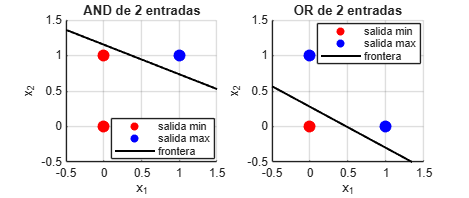

subplot(1,2,2); graficar_frontera(X, d, w, b, op.umbral, 'OR de 2 entradas');
guardar_fig('perc_fronteras');

## Reporte 1: las tres reglas en todas las compuertas

Como los pesos iniciales son aleatorios, cada combinacion se repite con 20 semillas distintas y se reporta el promedio de epocas y cuantas veces convergio.

compuertas = {'AND', 'OR'};
entradas   = [2 3 4];
reglas     = [1 2 3];
semillas   = 1:20;

filas = {};
for c = 1:numel(compuertas)
    for n = entradas
        [X, d] = compuerta(compuertas{c}, n, op.salida);
        for r = reglas
            ep = zeros(size(semillas)); conv = ep;
            for s = semillas
                o = op; o.regla = r; o.semilla = s;
                [~, ~, info] = perceptron(X, d, o);
                ep(s) = info.epocas; conv(s) = info.convergio;
            end
            filas(end+1, :) = {compuertas{c}, n, r, mean(ep), min(ep), max(ep), 100*mean(conv)}; %#ok<SAGROW>
        end
    end
end
R1 = cell2table(filas, 'VariableNames', ...
    {'Compuerta', 'Entradas', 'Regla', 'Epocas_prom', 'Epocas_min', 'Epocas_max', 'Convergio_pct'});
disp(R1)

    Compuerta    Entradas    Regla    Epocas_prom    Epocas_min    Epocas_max    Convergio_pct
    _________    ________    _____    ___________    __________    __________    _____________

     {'AND'}        2          1           4.6           2              8             100     
     {'AND'}        2          2           4.8           2              6             100     
     {'AND'}        2          3          4.85           2              7             100     
     {'AND'}        3          1          7.75           2             15             100     
     {'AND'}        3          2          7.95           2             18             100     
     {'AND'}        3          3           7.4           2             14             100     
     {'AND'}        4          1         17.45           4             31             100     
     {'AND'}        4          2         17.95           7             31             100     
     {'AND'}        4          3            14   

writetable(R1, 'informe/tablas/perc_reglas.csv');

## Reporte 2: efecto de alpha con la regla 3

alphas = [0.01 0.05 0.1 0.3 0.5 1];
filas = {};
for c = 1:numel(compuertas)
    for n = entradas
        [X, d] = compuerta(compuertas{c}, n, op.salida);
        for a = alphas
            ep = zeros(size(semillas)); conv = ep;
            for s = semillas
                o = op; o.regla = 3; o.alpha = a; o.semilla = s;
                [~, ~, info] = perceptron(X, d, o);
                ep(s) = info.epocas; conv(s) = info.convergio;
            end
            filas(end+1, :) = {compuertas{c}, n, a, mean(ep), 100*mean(conv)}; %#ok<SAGROW>
        end
    end
end
R2 = cell2table(filas, 'VariableNames', {'Compuerta', 'Entradas', 'Alpha', 'Epocas_prom', 'Convergio_pct'});
disp(R2)

    Compuerta    Entradas    Alpha    Epocas_prom    Convergio_pct
    _________    ________    _____    ___________    _____________

     {'AND'}        2        0.01         24.2            100     
     {'AND'}        2        0.05          6.9            100     
     {'AND'}        2         0.1         4.85            100     
     {'AND'}        2         0.3         5.25            100     
     {'AND'}        2         0.5          4.6            100     
     {'AND'}        2           1          4.8            100     
     {'AND'}        3        0.01           18            100     
     {'AND'}        3        0.05         7.75            100     
     {'AND'}        3         0.1          7.4            100     
     {'AND'}        3         0.3          9.1            100     
     {'AND'}        3         0.5         7.75            100     
     {'AND'}        3           1         7.95            100     
     {'AND'}        4        0.01         20.9            100

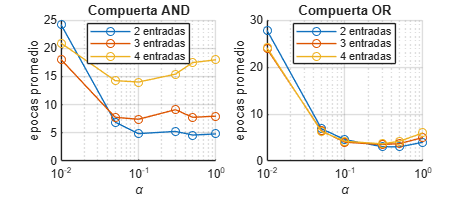

writetable(R2, 'informe/tablas/perc_alpha.csv');

figure('Position', [100 100 900 380]);
for c = 1:2
    subplot(1, 2, c); hold on
    for n = entradas
        k = strcmp(R2.Compuerta, compuertas{c}) & R2.Entradas == n;
        plot(R2.Alpha(k), R2.Epocas_prom(k), '-o', 'DisplayName', sprintf('%d entradas', n));
    end
    set(gca, 'XScale', 'log'); grid on
    xlabel('\alpha'); ylabel('epocas promedio'); title(['Compuerta ' compuertas{c}]);
    legend('Location', 'best');
end
guardar_fig('perc_alpha');

## Reporte 3: efecto del umbral

umbrales = [-1 -0.5 0 0.5 1 2];
filas = {};
for c = 1:numel(compuertas)
    [X, d] = compuerta(compuertas{c}, 2, op.salida);
    for u = umbrales
        ep = zeros(size(semillas)); conv = ep;
        for s = semillas
            o = op; o.umbral = u; o.semilla = s;
            [~, ~, info] = perceptron(X, d, o);
            ep(s) = info.epocas; conv(s) = info.convergio;
        end
        filas(end+1, :) = {compuertas{c}, u, mean(ep), 100*mean(conv)}; %#ok<SAGROW>
    end
end
R3 = cell2table(filas, 'VariableNames', {'Compuerta', 'Umbral', 'Epocas_prom', 'Convergio_pct'});
disp(R3)

    Compuerta    Umbral    Epocas_prom    Convergio_pct
    _________    ______    ___________    _____________

     {'AND'}        -1           8             100     
     {'AND'}      -0.5        6.95             100     
     {'AND'}         0        4.85             100     
     {'AND'}       0.5         4.1             100     
     {'AND'}         1         2.8             100     
     {'AND'}         2         2.4             100     
     {'OR' }        -1        9.55             100     
     {'OR' }      -0.5         6.6             100     
     {'OR' }         0        4.55             100     
     {'OR' }       0.5         2.4             100     
     {'OR' }         1        1.95             100     
     {'OR' }         2         3.3             100     



writetable(R3, 'informe/tablas/perc_umbral.csv');

## Reporte 4: salida codificada en {0,1} en vez de {-1,1}

Con la regla 1 (dW = d*x) esto importa mucho, porque cuando d = 0 la correccion es cero y la neurona no aprende nada de esos patrones.

filas = {};
for cod = {[-1 1], [0 1]}
    for c = 1:numel(compuertas)
        [X, d] = compuerta(compuertas{c}, 2, cod{1});
        for r = reglas
            ep = zeros(size(semillas)); conv = ep;
            for s = semillas
                o = op; o.regla = r; o.salida = cod{1}; o.semilla = s;
                [~, ~, info] = perceptron(X, d, o);
                ep(s) = info.epocas; conv(s) = info.convergio;
            end
            filas(end+1, :) = {mat2str(cod{1}), compuertas{c}, r, mean(ep), 100*mean(conv)}; %#ok<SAGROW>
        end
    end
end
R4 = cell2table(filas, 'VariableNames', {'Salida', 'Compuerta', 'Regla', 'Epocas_prom', 'Convergio_pct'});
disp(R4)

      Salida      Compuerta    Regla    Epocas_prom    Convergio_pct
    __________    _________    _____    ___________    _____________

    {'[-1 1]'}     {'AND'}       1          4.6             100     
    {'[-1 1]'}     {'AND'}       2          4.8             100     
    {'[-1 1]'}     {'AND'}       3         4.85             100     
    {'[-1 1]'}     {'OR' }       1            3             100     
    {'[-1 1]'}     {'OR' }       2            4             100     
    {'[-1 1]'}     {'OR' }       3         4.55             100     
    {'[0 1]' }     {'AND'}       1          100               0     
    {'[0 1]' }     {'AND'}       2          4.6             100     
    {'[0 1]' }     {'AND'}       3          6.9             100     
    {'[0 1]' }     {'OR' }       1          100               0     
    {'[0 1]' }     {'OR' }       2            3             100     
    {'[0 1]' }     {'OR' }       3         6.85             100     



writetable(R4, 'informe/tablas/perc_codificacion.csv');

## Curva de aprendizaje: errores por epoca en la AND de 4 entradas

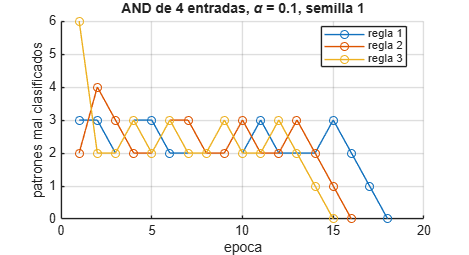

figure('Position', [100 100 700 380]); hold on
[X, d] = compuerta('AND', 4, op.salida);
for r = reglas
    o = op; o.regla = r;
    [~, ~, info] = perceptron(X, d, o);
    plot(1:info.epocas, info.errores_por_epoca, '-o', 'DisplayName', sprintf('regla %d', r));
end
grid on; xlabel('epoca'); ylabel('patrones mal clasificados');
title('AND de 4 entradas, \alpha = 0.1, semilla 1'); legend('Location', 'best');
guardar_fig('perc_curva_and4');